[x,fs] = audioread("matlab practice\Audio Signal Processing\piano.wav")

x =          0         0
         0         0
         0         0
         0         0
   -0.0000         0
   -0.0000    0.0000
   -0.0001    0.0000
   -0.0001    0.0001
   -0.0001    0.0001
   -0.0001    0.0001


fs = 44100

x = x(:,1);

N = length(x);
t = (0:N-1)/fs;
N/fs

ans = 6.1539

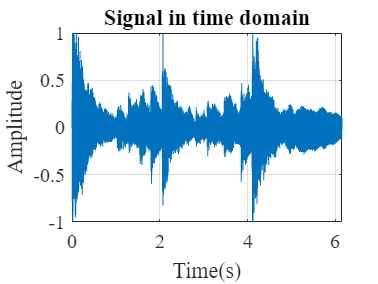

%plot time domain of the audio
plot(t, x)
grid on
set(gca,'Fontname','Times New Roman','FontSize',12)
xlabel('Time(s)')
ylabel('Amplitude')
title('Signal in time domain')

%stats information
maxValue = max(x)

maxValue = 1.0000

minValue = min(x)

minValue = -1.0000

meanValue = mean(x)

meanValue = 1.5718e-05

stdValue = std(x)

stdValue = 0.1480

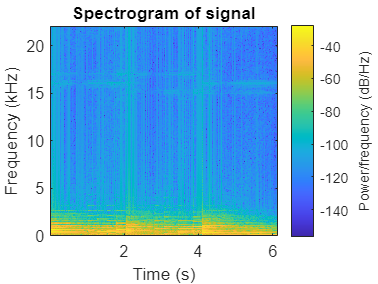

spectrogram(x,1024,512,1024,fs, 'yaxis')
title('Spectrogram of signal')

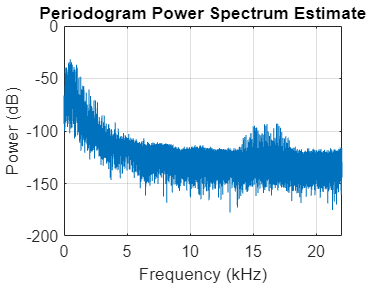

%Periodogram plot
w = hanning(N,'periodic');
periodogram(x,w,N,fs,'power')

[X,f] = periodogram(x,w,N,fs,'power');
X = 20*log10(sqrt(X)*sqrt(2));

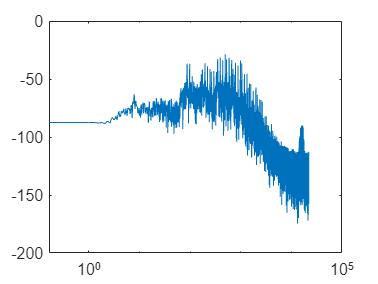

semilogx(f,X)

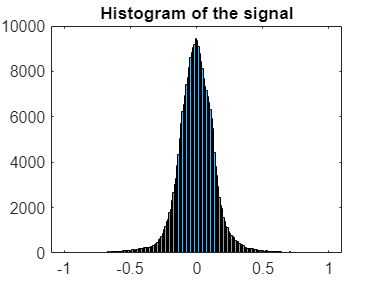

%plot histogram
histogram(x)
title('Histogram of the signal')